% Opgave 2.1

X = sqrt((4.65/log(0.3))^4 - 2*sind(32.54))

X = 14.8806


% Opgave 2.2
% a
a = [3 -3 0; 5 0 -1; 6 2 1]

a =      3    -3     0
     5     0    -1
     6     2     1


b = [2 3 1; -2 0 0; 0 2 3]

b =      2     3     1
    -2     0     0
     0     2     3



c = a-b

c =      1    -6    -1
     7     0    -1
     6     0    -2



%b

P = [3 -1; 0 2]

P =      3    -1
     0     2


Q = [3 2; 1 0]

Q =      3     2
     1     0



sol = P*inv(Q)

sol =    -0.5000    4.5000
    1.0000   -3.0000



% c
a = [4; -1]

a =      4
    -1


b = [2 1]

b =      2     1



c = a' + b

c =      6     0



fprintf('Opgave 2.3')

Opgave 2.3

t = linspace(-1, 1 , 9)

t =    -1.0000   -0.7500   -0.5000   -0.2500         0    0.2500    0.5000    0.7500    1.0000


u = linspace(-1.5, 2.5, 9)

u =    -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000



fprintf('Opgave 2.4')

Opgave 2.4

X = [5 -1 9; 4 8 0; -2 -3 2; 0 1 3]

X =      5    -1     9
     4     8     0
    -2    -3     2
     0     1     3


b = X(2, 1) % parantes for indeks, og indeks starter v. 1

b = 4

q = X(2, 1:3)

q =      4     8     0


r = X(1:4, 2)

r =     -1
     8
    -3
     1


S = X(1:3, 1:2)

S =      5    -1
     4     8
    -2    -3



fprintf('Opgave 2.5')

Opgave 2.5


v = [2 4 7 8];
w = 7*v.^2 % for at alle elementer bliver opløftet brug .^

w =     28   112   343   448




a = [-1 -3 5 1 2];
b = [-4 8 2 -1 5];

c = log((a./b).^2) % igen noget med . for alle elementer

c =    -2.7726   -1.9617    1.8326         0   -1.8326



t = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];

f = exp(-2*t) .* (3*cos(5.*t) - 4*sin(5.*t))

f =     3.0000    0.5854   -1.1697   -2.0733   -2.1953   -1.7648   -1.0646   -0.3468    0.2153    0.5418    0.6343



p = [1 2 3 4 5 6];
q = 5./(p.^2 - 2.*p +7)

q =     0.8333    0.7143    0.5000    0.3333    0.2273    0.1613



fprintf('Opgave 2.6')

Opgave 2.6

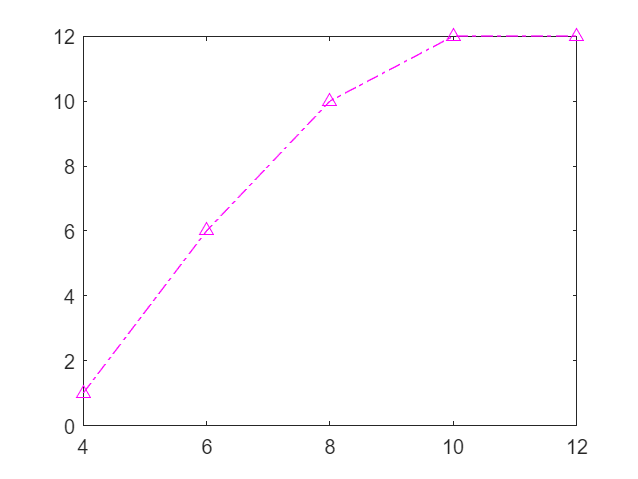


p = [4 6 8 10 12];
q = [1 6 10 12 12];

plot(p, q, '-^', Color='magenta', LineStyle='-.')


fprintf('Opgave 2.7')

Opgave 2.7

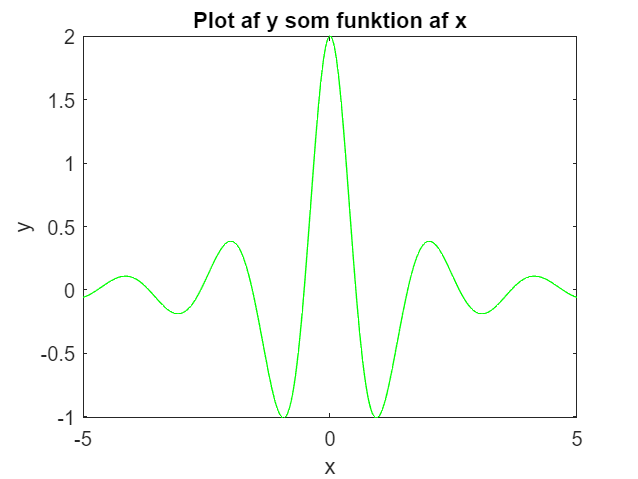

syms x

f = 2*cos(3*x)/(x^2 + 1);

y = [0 0.3 -0.4 0.5 -1 1.9 -1 0.4 0.2 0.4 -0.2];

fplot(f, [-5, 5], Color='g')
title('Plot af y som funktion af x')
xlabel('x')
ylabel('y')


fprintf('Opgave 2.8')

Opgave 2.8

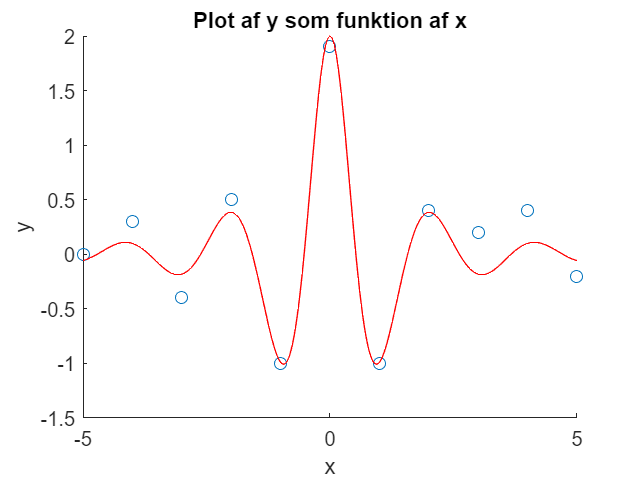


x = linspace(-5, 5, 11);
y = [0 0.3 -0.4 0.5 -1 1.9 -1 0.4 0.2 0.4 -0.2];
scatter(x, y, Marker="o")
hold on

fplot(f, [-5, 5], Color='r')

title('Plot af y som funktion af x')
xlabel('x')
ylabel('y')

hold off


fprintf('Opgave 2.15')

Opgave 2.15

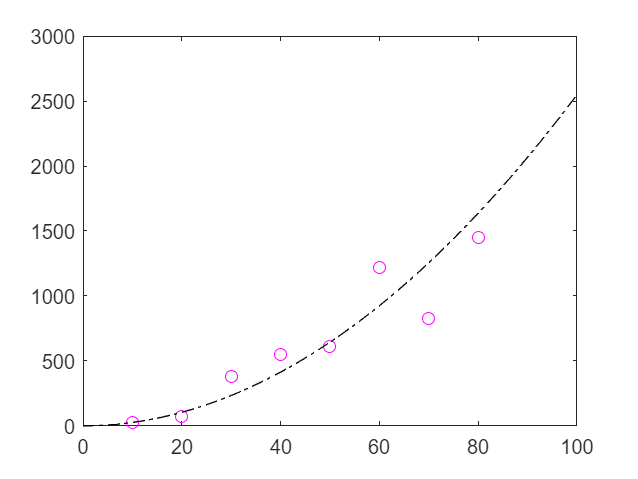


v = [10 20 30 40 50 60 70 80]; % m/s
F = [25 70 380 550 610 1220 830 1450]; % Newton


plot(v, F, LineStyle="none", Color='magenta', Marker='o')

hold on

syms v
F_func = 0.2741*v^1.9842;
interval = [0, 100];

fplot(F_func, interval, LineStyle="-.", Color='black')

hold off


fprintf('Opgave 2.16')

Opgave 2.16

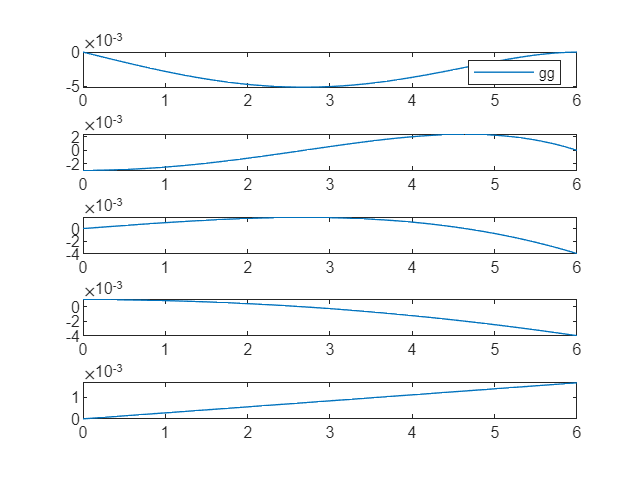


syms x

L = 6;  E = 5e11;   I = 0.0003; omega = 250000;

x_int = [0, L];

% Nedbøjning
y = omega/(120*E*I*L) * (-x^5 + 2*L^2*x^3 - L^4*x);
subplot(5, 1, 1)
fplot(y, x_int)
legend('gg')

% Hældning
hld = diff(y, x);

subplot(5, 1, 2)
fplot(hld,x_int)

% Moment
mom = diff(hld, x);

subplot(5,1,3)
fplot(mom, x_int)

% Forskydning
forsk = diff(mom, x);

subplot(5,1,4)
fplot(forsk, x_int)

% Last
last = -diff(forsk, x);

subplot(5,1,5)
fplot(last, x_int)